# Actividad 1.3: Parametrización de trayectorias

José Diego Tomé Guardado A01733345

#### **Generar la parametrización de las siguientes trayectorias en un plano 2D**

#### **Ejercicio 1 - Figura rombo**

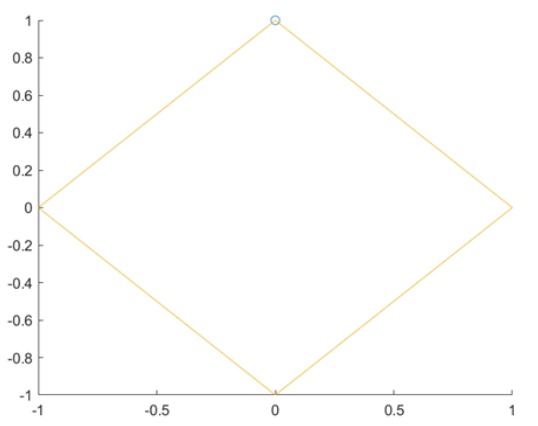

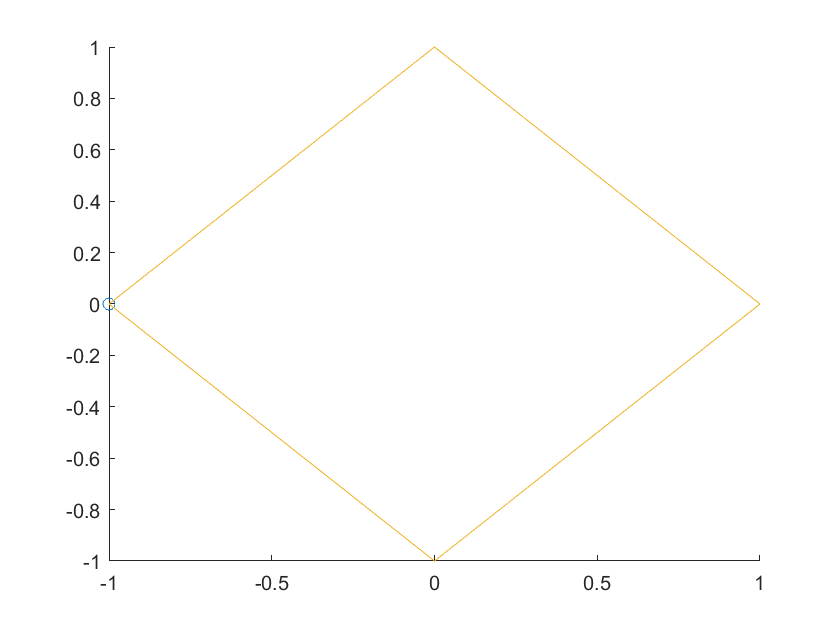

%Se define el parámetro "t" para la proyección de trayectoria
tiempo=[1:1.5:13];

%Se normaliza el intervalo de tiempo al intervalo de variación del ángulo
t1= normalize(tiempo,"range",[pi,5*pi]);

%Obtenemos las ecuaciones dependientes del tiempo
x1= cos(t1);
y1= sin(t1);

%graficamos la trayectoria 
figure(1)
comet(x1,y1)

- **Análisis**

En las ecuaciones vamos a calcular las coordenadas x y y del rombo con la implementación de las funciones trigonométricas de coseno y seno para poder ir generando los puntos del rombo que estarán basados en el tiempo normalizado de t1, estas ecuaciones podemos decir que primeramente para observar como pudimos ir sacandolas me base en las coordenadas paramétricas de un círculo ***x = cos(t)*** y ***y = sin(t); ***donde t sera representado como el ángulo. Al poder utilizar estas ecuaciones me di cuenta de que podemos tener una normalización del tiempo para que el rombo se traze correctamente en vez del circulo.

La normalización del tiempo es importante para pdoer formar el rombo ya que controla como se van a distribuir los puntos en el plano xy a lo largo de un intervalo de tiempo. Al tener un incremento de 1.5 podemos tener menos puntos y la figura podría ser más simplificada con menos lados, también debemos de indicar que al aumentar el incremento de tiempo también debemos aumentar el último número del vector, donde en lugar de tomar valores de tiempo que van de 1 a 18 estos se normalizan para poder cubrir un rango angular para formar el rombo controla la duración total del intervalo de tiempo, el número de puntos generados y la densidad de puntos en la figura trazada. Significando que hay una densidad uniforme de puntos a lo largo de las cuatro esquinas del rombo para poder formar esta apariencia simétrica. Seleccionamos el rango de ***π***  a **5*****π*** debido a que abarca un ángulo de **4*****π*** para poder cubrir más allá los **360 grados** donde tenemos más control de la inclinación de los lados.

#### Ejercicio 2 - Figura Hexágono

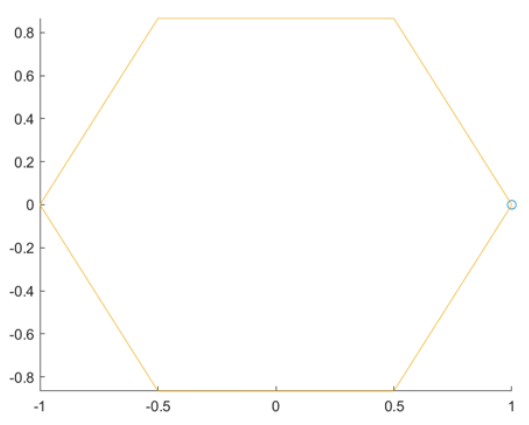

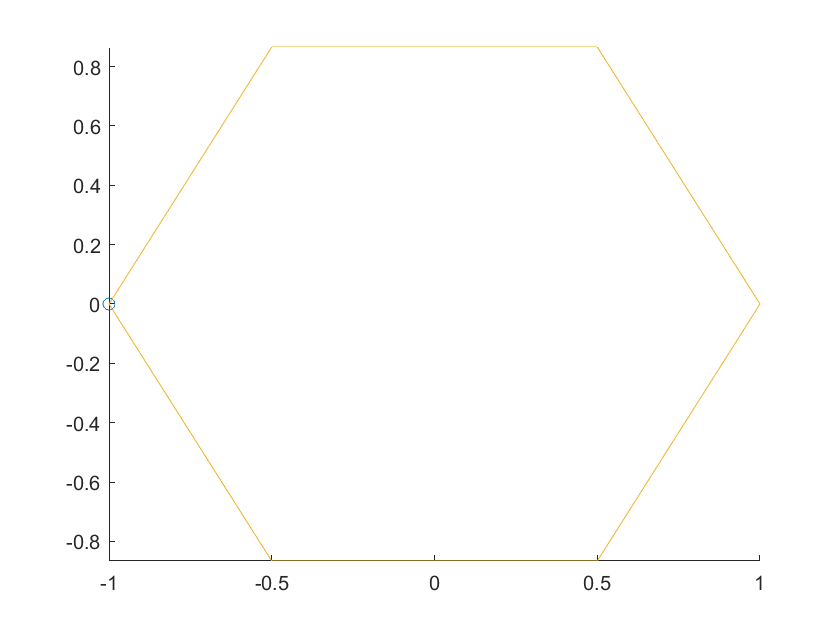

%Se define el parámetro "t" para la proyección de trayectoria
tiempo=[1:1:13];

%Se normaliza el intervalo de tiempo al intervalo de variación del ángulo
t2= normalize(tiempo,"range",[pi,5*pi]);

%Obtenemos las ecuaciones dependientes del tiempo
x2= cos(t2);
y2= sin(t2);

%graficamos la trayectoria 
figure(2)
comet(x2,y2)

- **Análisis**

Ahora para poder hacer el trazado del hexágono también que se puede ver que tiene un rango en x de **-1 **a **1** y un rango en y que también va de **-1 **a **1**, ocuparemos las mismas ecuaciones de x y y definidas anteriormente en el rombo ya que básicamente se va a efectuar mismo pero cambiando el tiempo que se va a estar normalizando para poder lograr que se trazen más aristas. Por lo que para poder lograr esto determinamos el tiempo con un valor del ***incremento en 1*** para poder tener más puntos ya que haciendo pruebas pude darme cuenta que al poder disminuir este se generan más puntos en el mismo intervalo de tiempo, aumentando la densidad de los puntos a lo largo de la trayectoria.

Con este incremento de 1 podemos ver como los puntos generados van a estar más cerca entre sí a lo largo de toda la trayectoria significando que la figura pueda tener más lados y se considere más compleja como en este caso un hexágono. Teniendo declaradas las mismas ecuaciones trigonómetricas de ***x1= cos(t1)*** y ***y1= sin(t1)*** pero teniendo el cambio en la distribución de los puntos para generar el polígono con más lados.

#### Ejercicio 3 - Figura Dodecágono (12 lados)

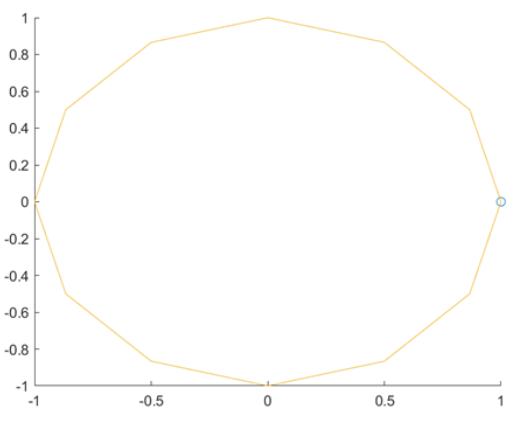

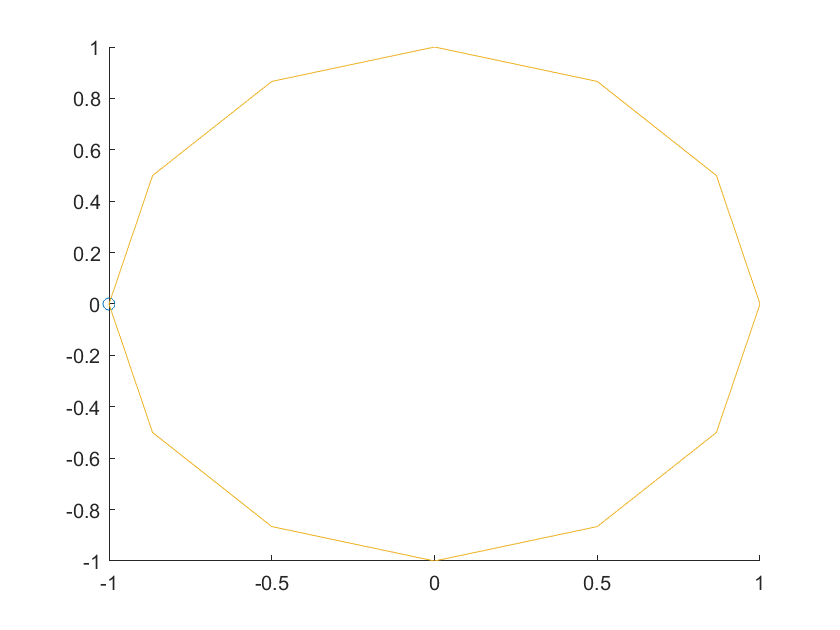

%Se define el parámetro "t" para la proyección de trayectoria
tiempo=[1:0.5:13];

%Se normaliza el intervalo de tiempo al intervalo de variación del ángulo
t3= normalize(tiempo,"range",[pi,5*pi]);

%Obtenemos las ecuaciones dependientes del tiempo
x3= cos(t3);
y3= sin(t3);

%graficamos la trayectoria 
figure(3)
comet(x3,y3)

- **Análisis**

Finalmente continuaremos con la trayectoria de un polígono denominado como Dodecágono donde se tendran que hacer 12 lados para poder tener correctamente el trazado de toda la figura, además de contar con un rango de **-1 **a **1** para xy. Por lo que pude ir observando que tenemos el mismo valor del rango de **13** también para esta figura y mantenemos las mismas ecuaciones de ***x= cos(t)*** y ***y= sin(t)***. Debido a que no cambia estas ecuaciones ya que gracias a la normalización del tiempo podemos tener claro que solo cambio estos valores ***tiempo=[1:0.5:13];*** podremos lograr trazar más o menos aristas. Gracias a la pruebas que pude estar probando me di cuenta que cuando le baje el incremento medio número se estan trazando el doble de lados que tenia al principio entonces con ello pude comprender que en el hexágono tenia un incremento de **1** por lo que para un Dodecágono de **12 lados** solo tuve que bajar el incremento a la mitad dejandolo de 0.5 para mostrar los 12 lados.

#### Ejercicio 4 - Figura Flor con 9 pétalos

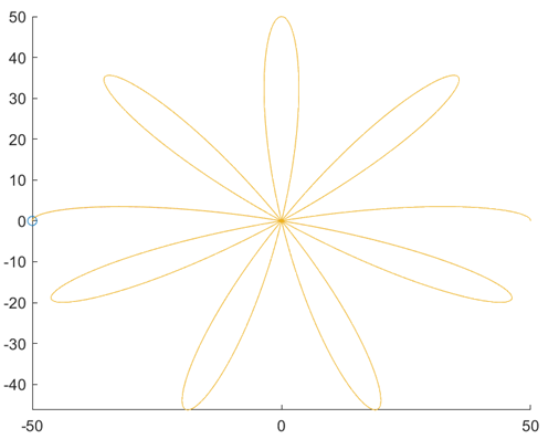

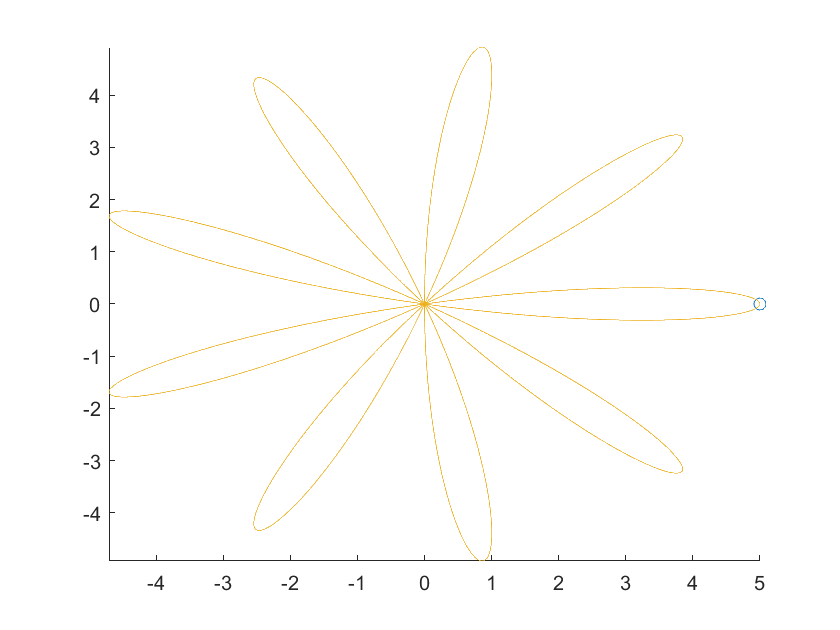

%Se define el parámetro "t" para la proyección de trayectoria
tiempo=[0:0.001:10];

%Se normaliza el intervalo de tiempo al intervalo de variación del ángulo
t= normalize(tiempo,"range",[0,pi]);

%Obtenemos las ecuaciones dependientes del tiempo
x4= 5*cos(9*t).*cos(t);
y4= 5*cos(9*t).*sin(t);

%graficamos la trayectoria 
figure(4)
comet(x4,y4)

- **Análisis**

Para poder comenzar a trazar ahora esta figura que asemeja a una flor de** 9 petálos** tendremos primeramente un tiempo que va desde **0** a **10** con ***pasos de 0.001***, ocuparemos de un incremento de los pasos minimo para poder trazar correctamente las curvas que se estaran viendo como los petálos de la flor, además de que se normalizara para la variación del ángulo que será de **0** a ***π*** que son 180 grados para dibujar una curva que represente un cuarto de circulo para mostrar el petálo.

Para poder tener correctamente una ecuación de x, podemos ver que se generaran con ***cos(t)*** y ***cos(9*t)*** esa multiplicación que representa el dibujo constante de los petálos, creando fluctuaciones peródicas en la dirección de x a medida que **t** va variando de **0** a ***π*** donde indicamos que cada petálo va a corresponder a un ciclo completo de cos(t) y para la función de ***cos(9*t)*** tendrá esta **frecuencia de 9** que va a determinar la cantidad de ciclos que se estarán trazando entonces como son 9 petálos por ello lo definiremos asi para que trace correctamente la cantidad.

La ecuación de y también tendrá los mismos valores que la ecuación de x porque estará haciendo las mismas fluctuaciones en la dirección pero ahora para generar los valores de coordenadas en el eje y.

#### Ejercicio 5 - Figura Flor con 15 pétalos

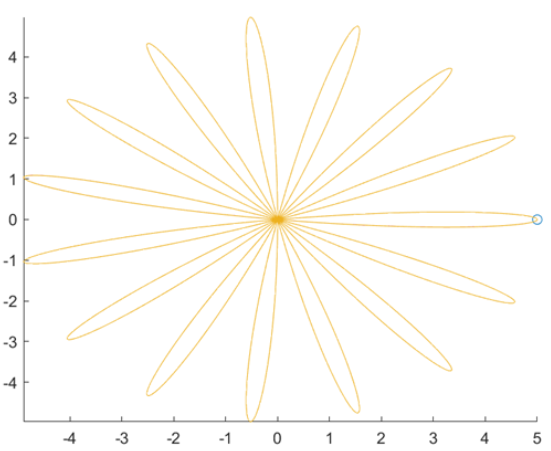

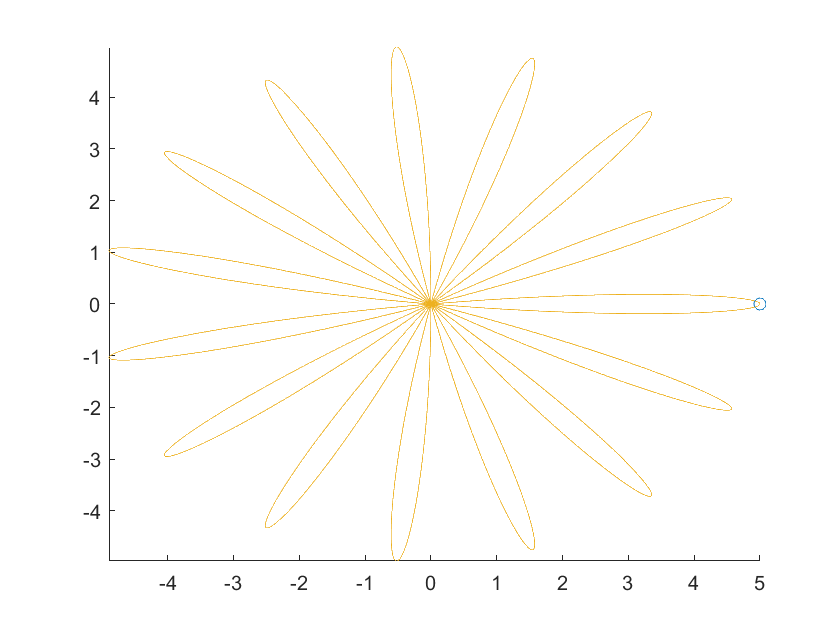

%Obtenemos las ecuaciones dependientes del tiempo
x5= 5*cos(15*t).*cos(t);
y5= 5*cos(15*t).*sin(t);

%graficamos la trayectoria 
figure(5)
comet(x5,y5)

- **Análisis**

En esta ocasión tendremos el mismo tiempo ya que lo que queremos es generar la misma figura de una flor por ello la normalización del tiempo y el tiempo en sí no tendran ningun cambio para generar esta figura. Lo que podemos observar que esta cambiando es el número de petálos que esta trazando esta figura como una flor pero de **15 petálos**. Es por ello que solo estaremos cambiando las ecuaciones de xy para en este caso tendremos la **frecuencia definida de 15 **para la función de ***cos(15*t)*** y de ***sin(15*t)*** determinando la cantidad de ciclos que se estarán trazando entonces como son 15 petálos lo definimos asi para que claramente en la trayectoria del trazado pueda correctamente estarse viendo los 15 petálos

#### Ejercicio 6 - Figura con 80 pétalos

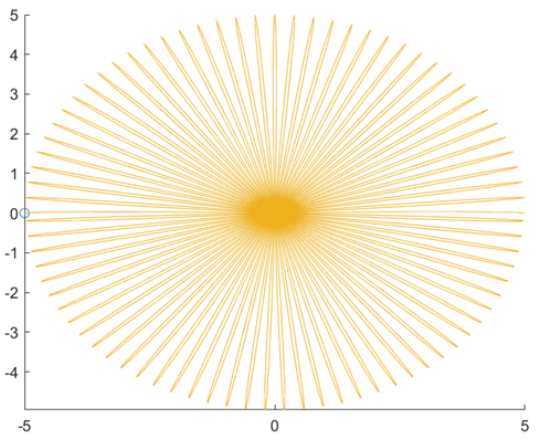

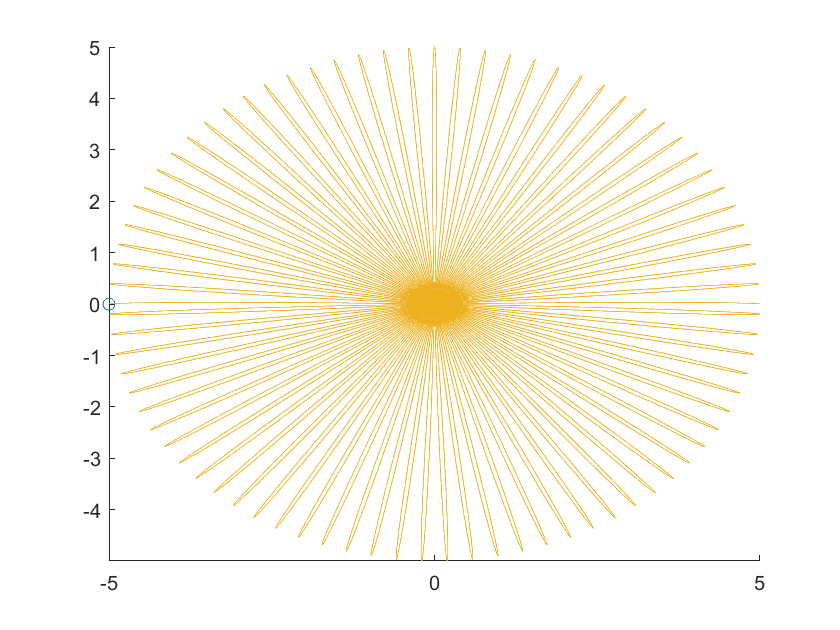

%Obtenemos las ecuaciones dependientes del tiempo
x6= 5*cos(80*t).*cos(t);
y6= 5*cos(80*t).*sin(t);

%graficamos la trayectoria 
figure(6)
comet(x6,y6)

- **Análisis**

Finalmente vamos a tener igualmente una flor pero tenemos que generar un aproximado de **80 petálos**, por lo que también tendremos la misma definición para el tiempo y para el incremento.  Teniendo una ecuación de x donde las ecuaciones se ocuparan con ***cos(t)*** teniendo las fluctuaciones en la dirección de x a medida de la variacion de la normalización del tiempo con la multiplicación de ***cos(80*t) ***donde también la ***frecuencia dada que en este caso será de 80*** va a representar los 80 petálos de la figura y determinará la cantidad de los ciclos que se dibujarán.